clear
clc
clf

set(0,'defaulttextinterpreter','latex')
rssiData = dlmread('RSSIdata.txt', '\t'); %#ok<DLMRD> 
d = [0:0.05:1, 1.2:0.2:5];

% Define the frequency range for BLE in Hertz
frequency = 2.4e9; % 2.4 GHz

% Speed of light in meters per second
speedOfLight = 3e8;

% Calculate the wavelength
lambda = speedOfLight / frequency;

% Calculated RSSI at distance d0 = 1m
rssi_d0 =  20*log(lambda/(4*pi));

% Calculated log values
y = zeros(length(d), 1);
z = zeros(length(d), 1);
avg_gamma = zeros(length(d), 1);

% Define path loss exponent value
gamma = 1.7;
% Define the standard deviation for Gaussian noise
sigma = 0;
% Define rng seed for repeated testing
rng(2019);

RSSI_d0 = -60;

for i = 1:1:length(d)
    y(i) = RSSI_d0 - 10*gamma*log10(d(i)) + sigma * randn;
    z(i) = rssi_d0 - 10*gamma*log(d(i));
end

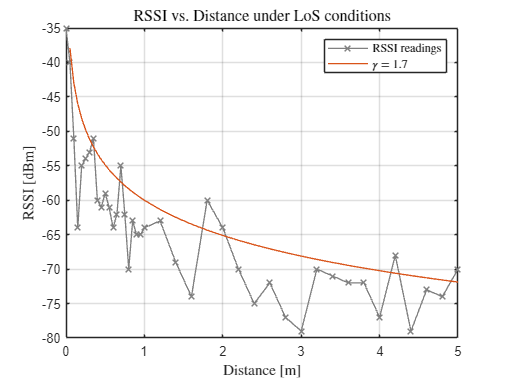

plot(d,rssiData,"-x",'LineWidth',1,'color', [.5 .5 .5]);
xlabel("Distance [m]");
ylabel("RSSI [dBm]");   
title("RSSI vs. Distance under LoS conditions",'FontSize',12)
hold on
plot(d,y,'LineWidth',1,'Color',[0.8500 0.3250 0.0980])
legend('RSSI readings', '$\gamma = 1.7$', 'Interpreter', 'latex');
grid on

% print -depsc rssiDistanceMPEB